%% This script will be in charge of uploading 
%% any video onto MATLAB and breaking it into frames 
%% Donavan Jeng

%read and upload video from folder
mike_tyson = VideoReader("PunchNet/Video_Data/test_clip_MT.mp4")

mike_tyson =   VideoReader with properties:

   General Properties:
            Name: 'test_clip_MT.mp4'
            Path: '/Users/donavanjeng/Documents/GitHub/PunchNet/Video_Data'
        Duration: 3.0933
     CurrentTime: 0
       NumFrames: <Calculating...> learn more
   Video Properties:
           Width: 640
          Height: 360
       FrameRate: 29.9700
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


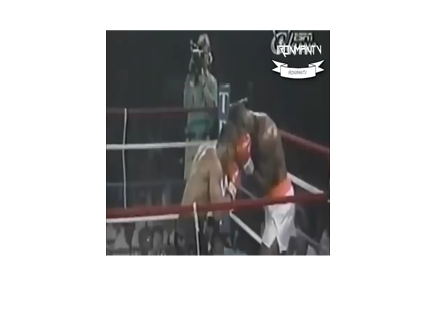

mike_tyson.CurrentTime = 0; % start from 0 seconds of the video
while hasFrame(mike_tyson) %reads the video for how many frames it has. Will also simultaneously resize each frame
    vidFrame = readFrame(mike_tyson); %reads frames 
    resizedFrame = imresize(vidFrame, [224,224]);
    imshow(resizedFrame)

end